## Descriptive statistics (traditional and robust)

Compute mean, median,  std, normalized MAD, skewness and medcouple for the variables of the input table citiesItaly.

% Load the dataset which shows
load citiesItaly.mat
disp('For additional information about this dataset')
disp(citiesItaly.Properties.Description)
% Find descriptive statistics
% Call to FSDA function grpstatsFS
% The output is a table of dimension p-by-6 where p is the number of variables of the input dataset.
TBL=grpstatsFS(citiesItaly);
disp(TBL)

                   mean     median     std       MAD      skewness    medcouple
                  ______    ______    ______    ______    ________    _________

    addedval       18096     18469    4941.6    6001.8     0.1079      -0.12451
    depos         7769.1    7661.1    2841.4    3150.5     1.0734      -0.03612
    pensions       10044    9975.2    1230.8    1170.6    0.31692      0.089163
    unemploy      10.173      6.42    7.8789    4.8778     1.0687       0.61846
    export         23.11     21.53    15.642    16.457     0.5797      0.066667
    bankrup       30.467     29.62     12.11     11.49     1.0067     -0.010969
    billsoverd    44.614      40.6  

Example of the use of grpstatsFS with grouping variable

%% grpstatsFS with second input the grouping variable.
load citiesItaly.mat
citiesItaly=normalize(citiesItaly,"zscore");
% The first 46 rows are referred to provinces located in northern Italy and
% the remaining in centre-south of Italy.
zone=[repelem("N",46) repelem("CS",57)]';
citiesItalyWithZone=citiesItaly;
% Add variable zone to citiesItaly
citiesItalyWithZone.zone=zone;
TBL=grpstatsFS(citiesItalyWithZone,"zone");
% First 6 columns are referred to province of the north. The remaning
% columns to the other provinces.
disp(TBL)

                   meanN      medianN      stdN       MADN      skewnessN    medcoupleN     meanCS     medianCS     stdCS      MADCS     skewnessCS    medcoupleCS
                  ________    ________    _______    _______    _________    __________    ________    ________    _______    _______    __________    ___________

    addedval        0.8044     0.77705    0.59219    0.43234     0.78292     -0.024878     -0.64917    -0.81901    0.76103    0.70833     0.83573        0.23097  
    depos          0.64951     0.57663     0.7793    0.37046      2.

Example of call to grpstatsFS with personalized statistics.

% The second element is empty, that is there is no grouping variable.
load citiesItaly.mat
% Just compute mean and median
stats=["mean" "median"];
TBL=grpstatsFS(citiesItaly,[],stats);
disp(TBL)

                   mean     median
                  ______    ______

    addedval       18096     18469
    depos         7769.1    7661.1
    pensions       10044    9975.2
    unemploy      10.173      6.42
    export         23.11     21.53
    bankrup       30.467     29.62
    billsoverd    44.614      40.6



### Histograms with grouping variable and clickable legends

Compare provinces located in north of Italy with those in centre and south part using  histogram with the elements in each bin grouped according to the grouping variable. Make the legends clickable, in the sense that if you click on a legend entry it is possible to hide/show a particular group. 

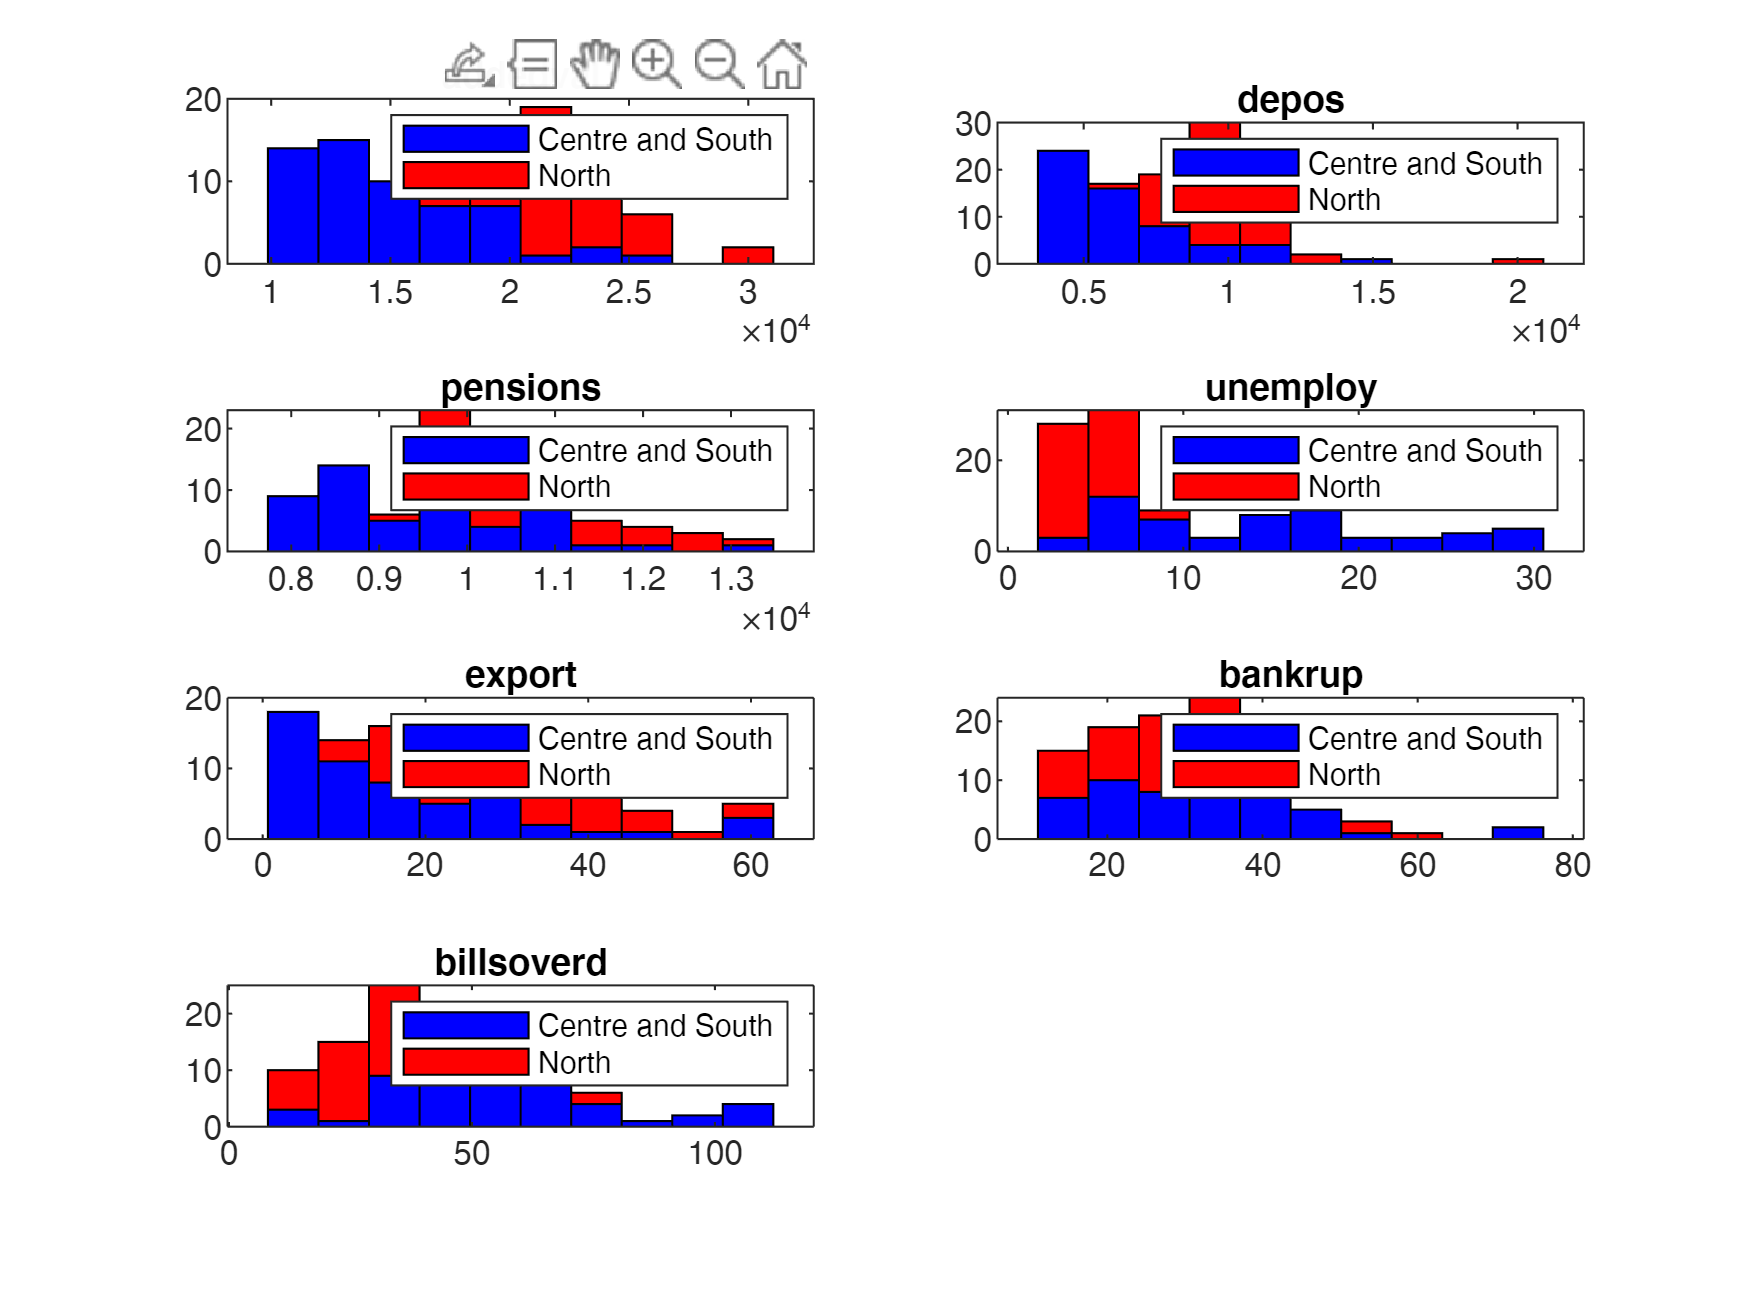

for j=1:7
    hj=subplot(4,2,j);
    % Create a histogram with elements in each bin grouped accouding to
    % zone by calling FSDA function histFS
    histFS(citiesItaly{:,j},10,zone,{'Centre and South' 'North'});
    title(hj,citiesItaly.Properties.VariableNames(j))
    % Make the legends clickable with FSDA function clickableMultiLegend
    clickableMultiLegend();
end

If the users click on the legend entry "North" the corresponding bins in the histograms are hidden (see preview below)

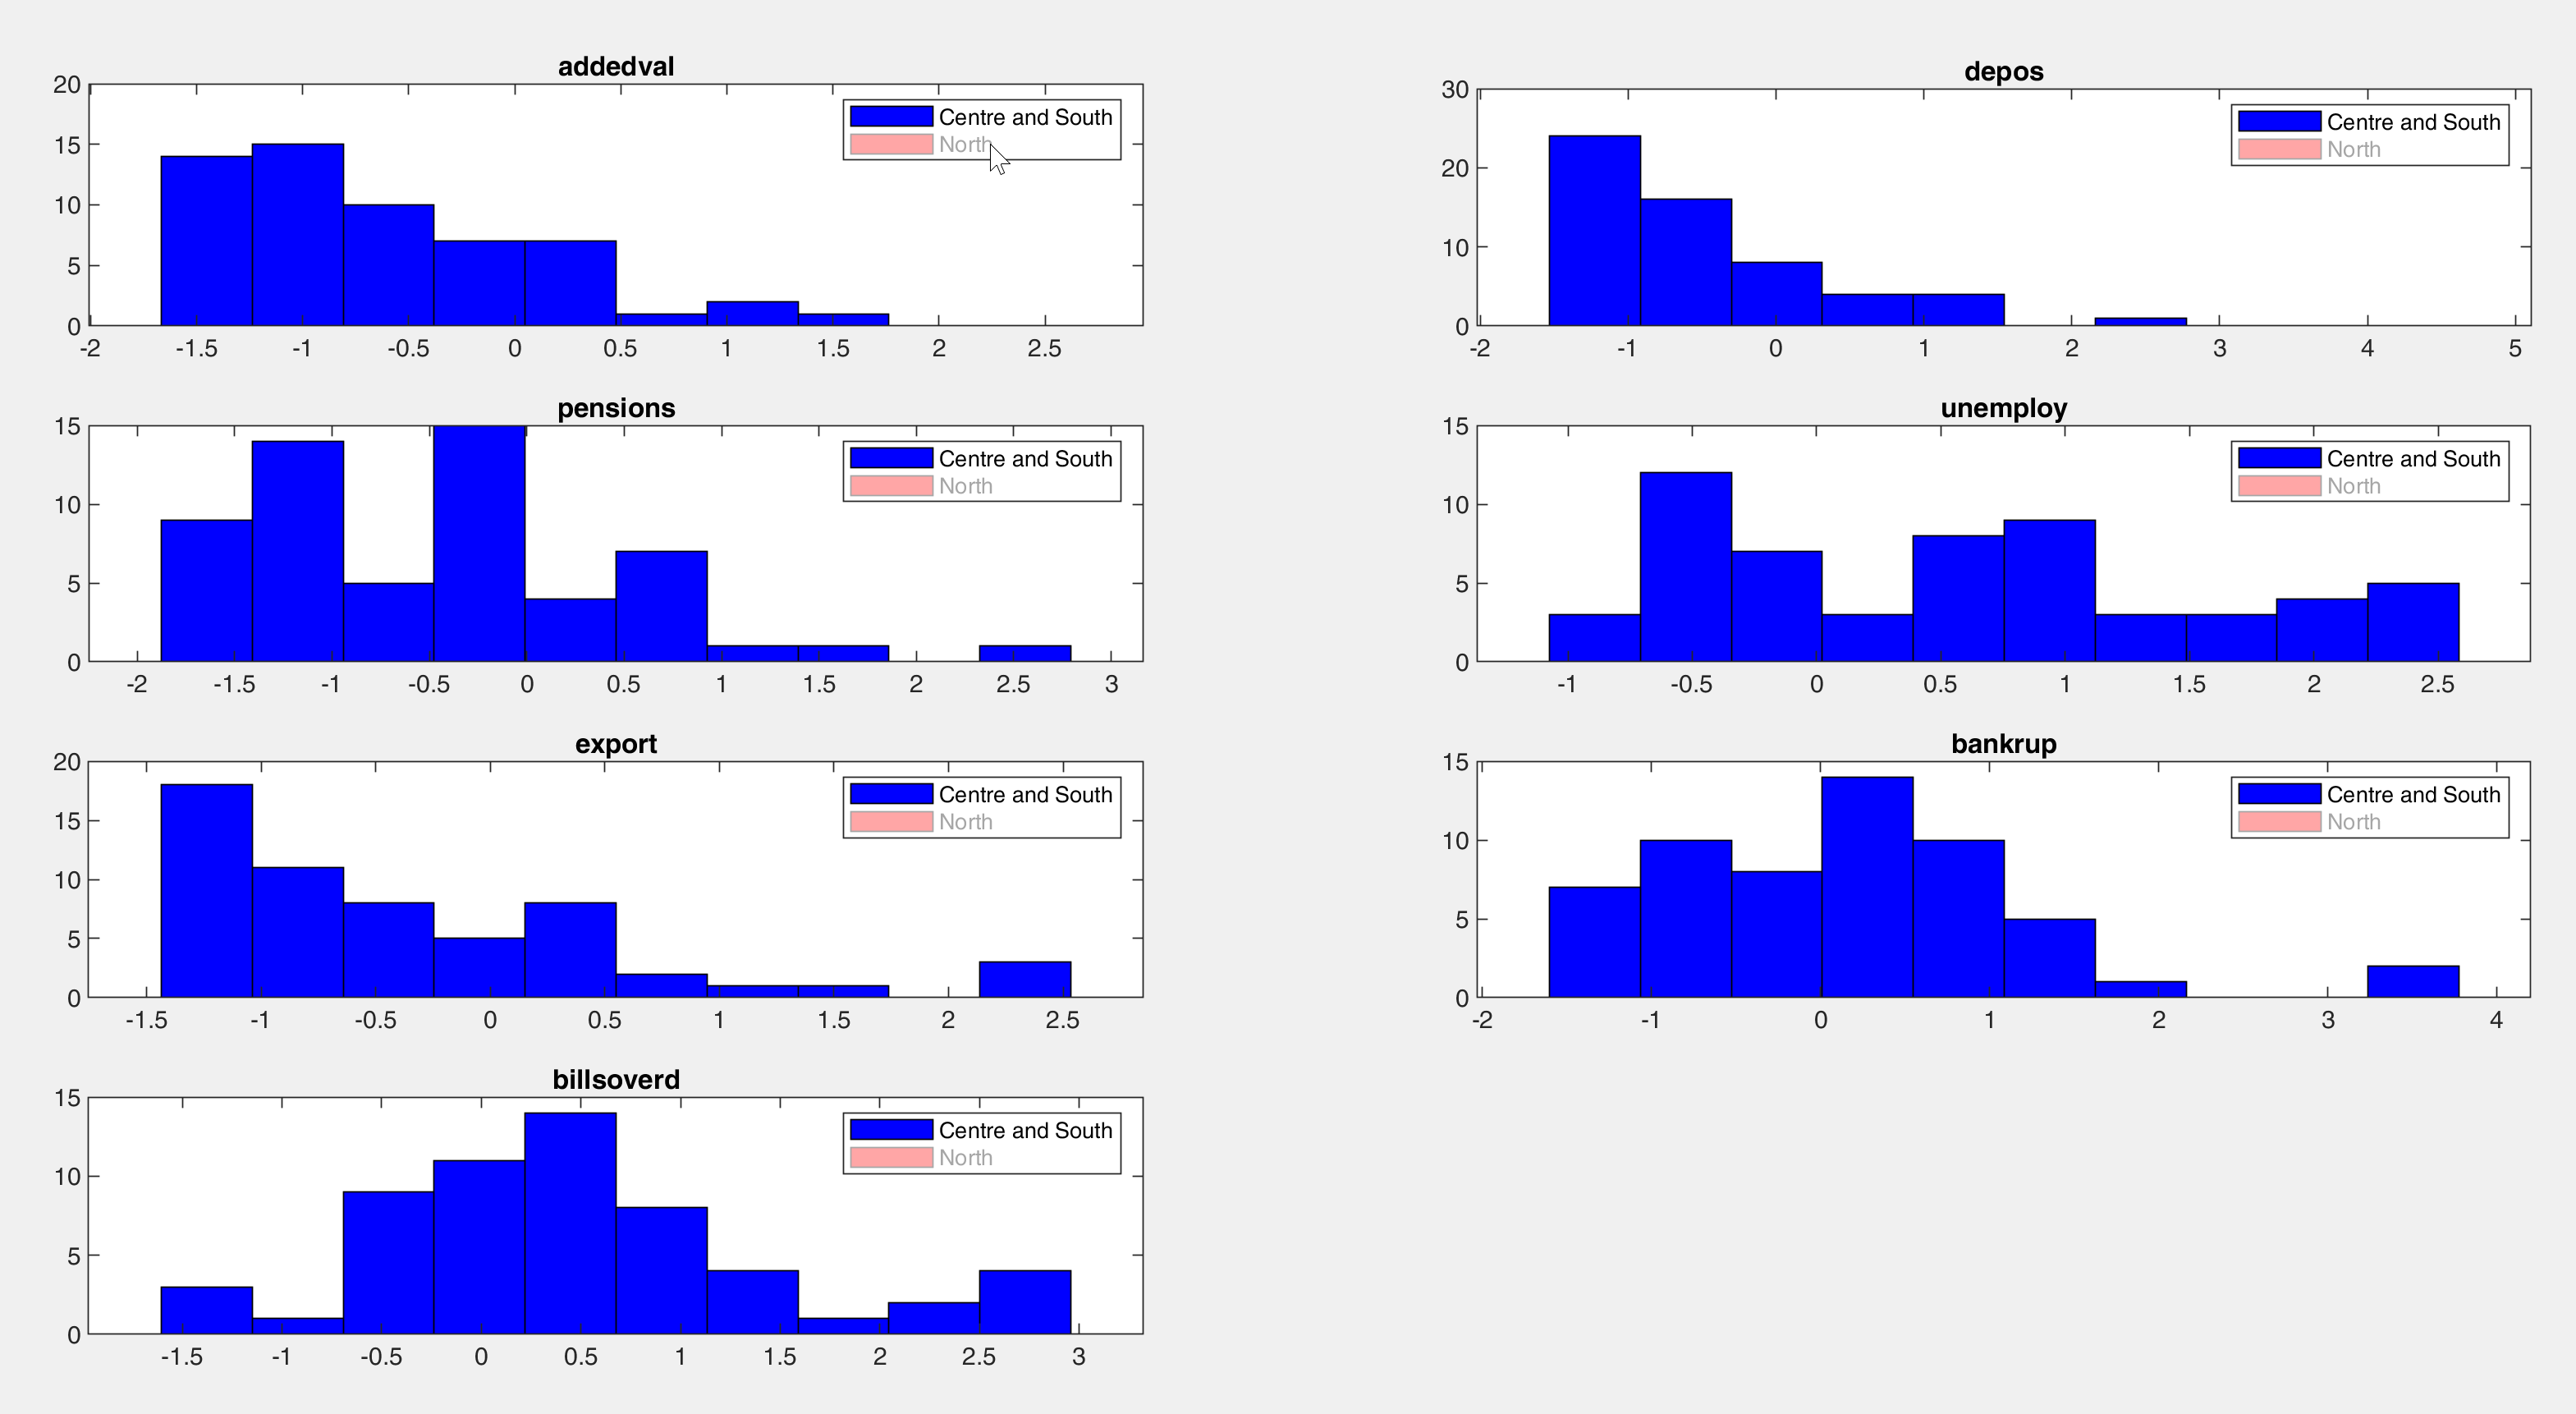

### Scatterplot matrix with clickable multilegend

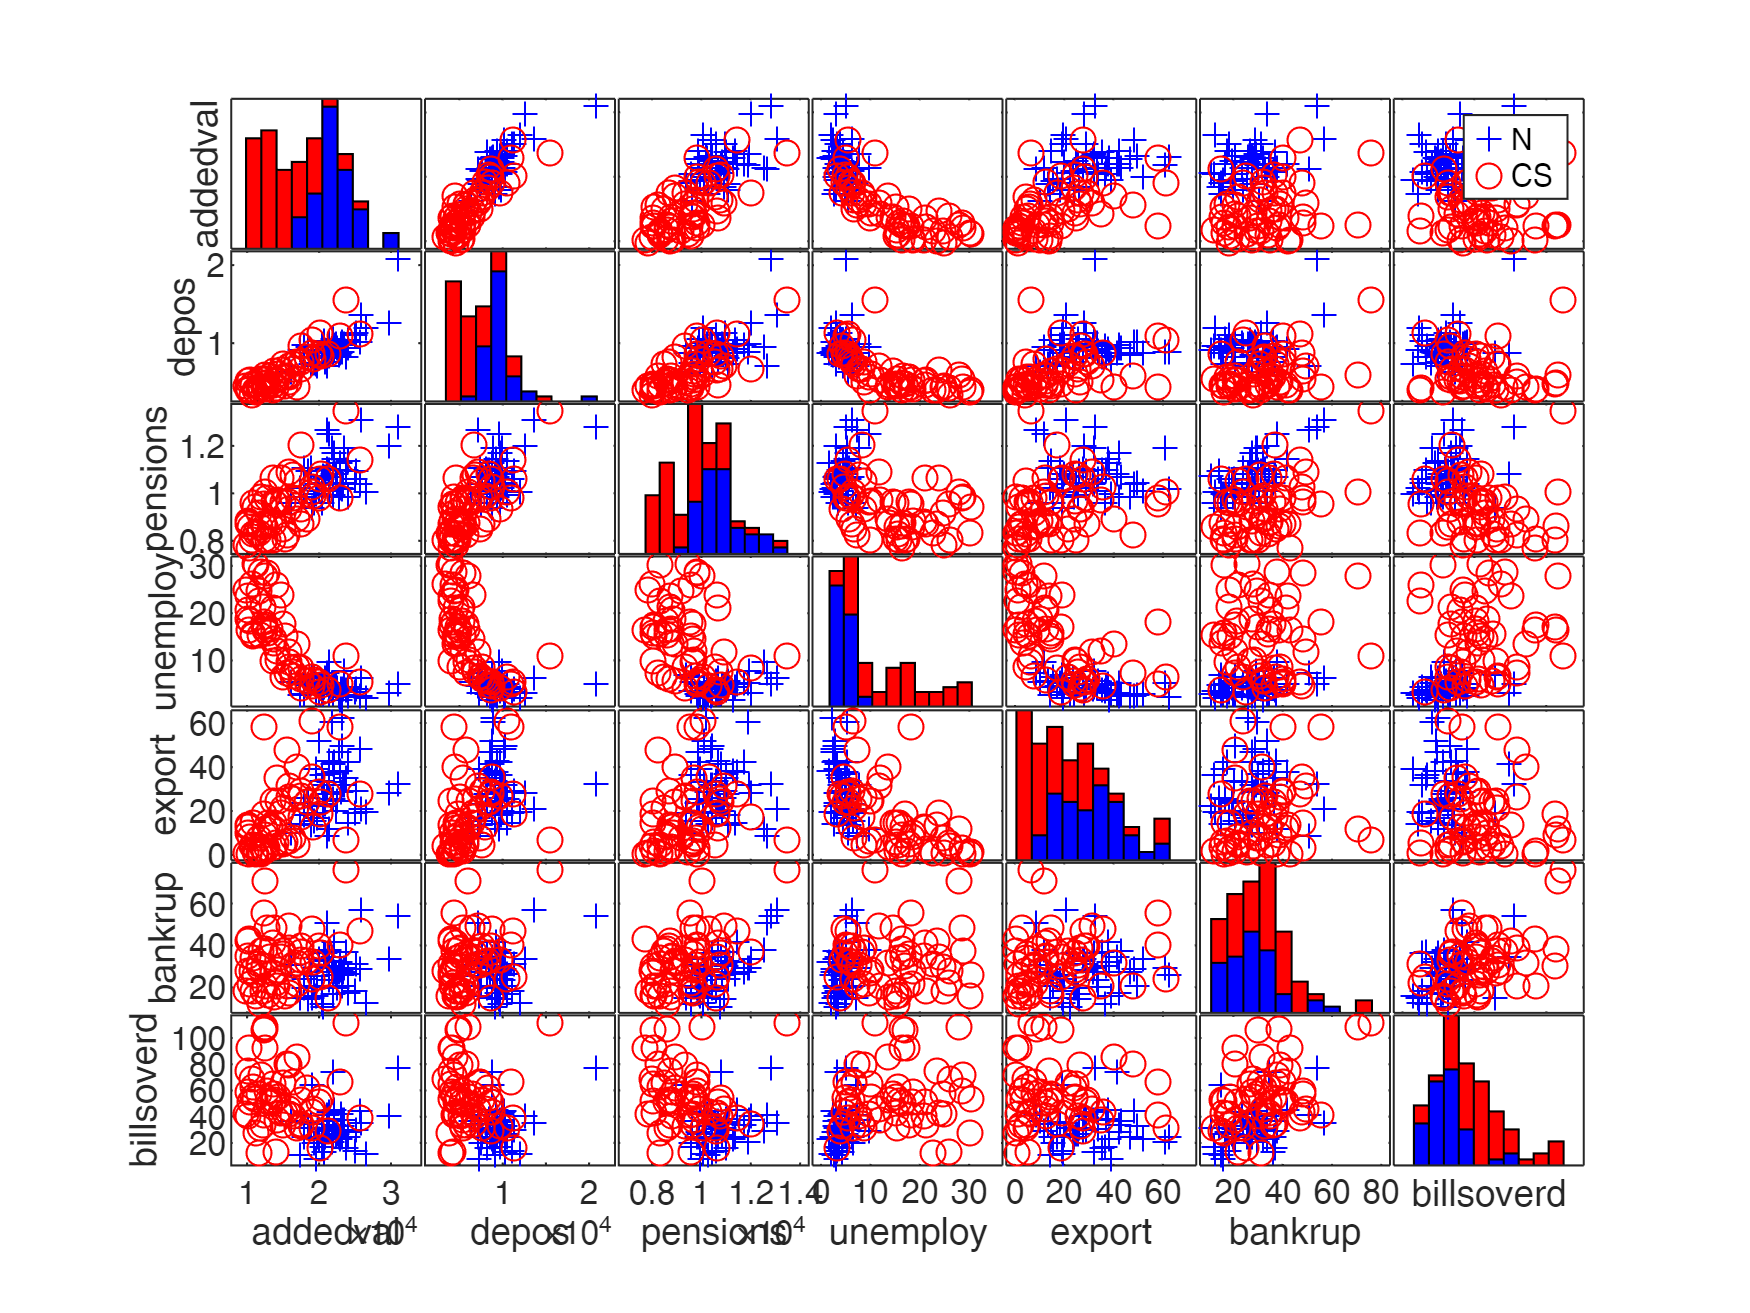

% Call to FSDA function spmplot
spmplot(citiesItaly,'group',zone);

For example, clicking on "N" in the legend it is possible to hide/show the corresponding units which belong to the north of Italy both in the scatters and in the hisrograms alonng the main diagonal.

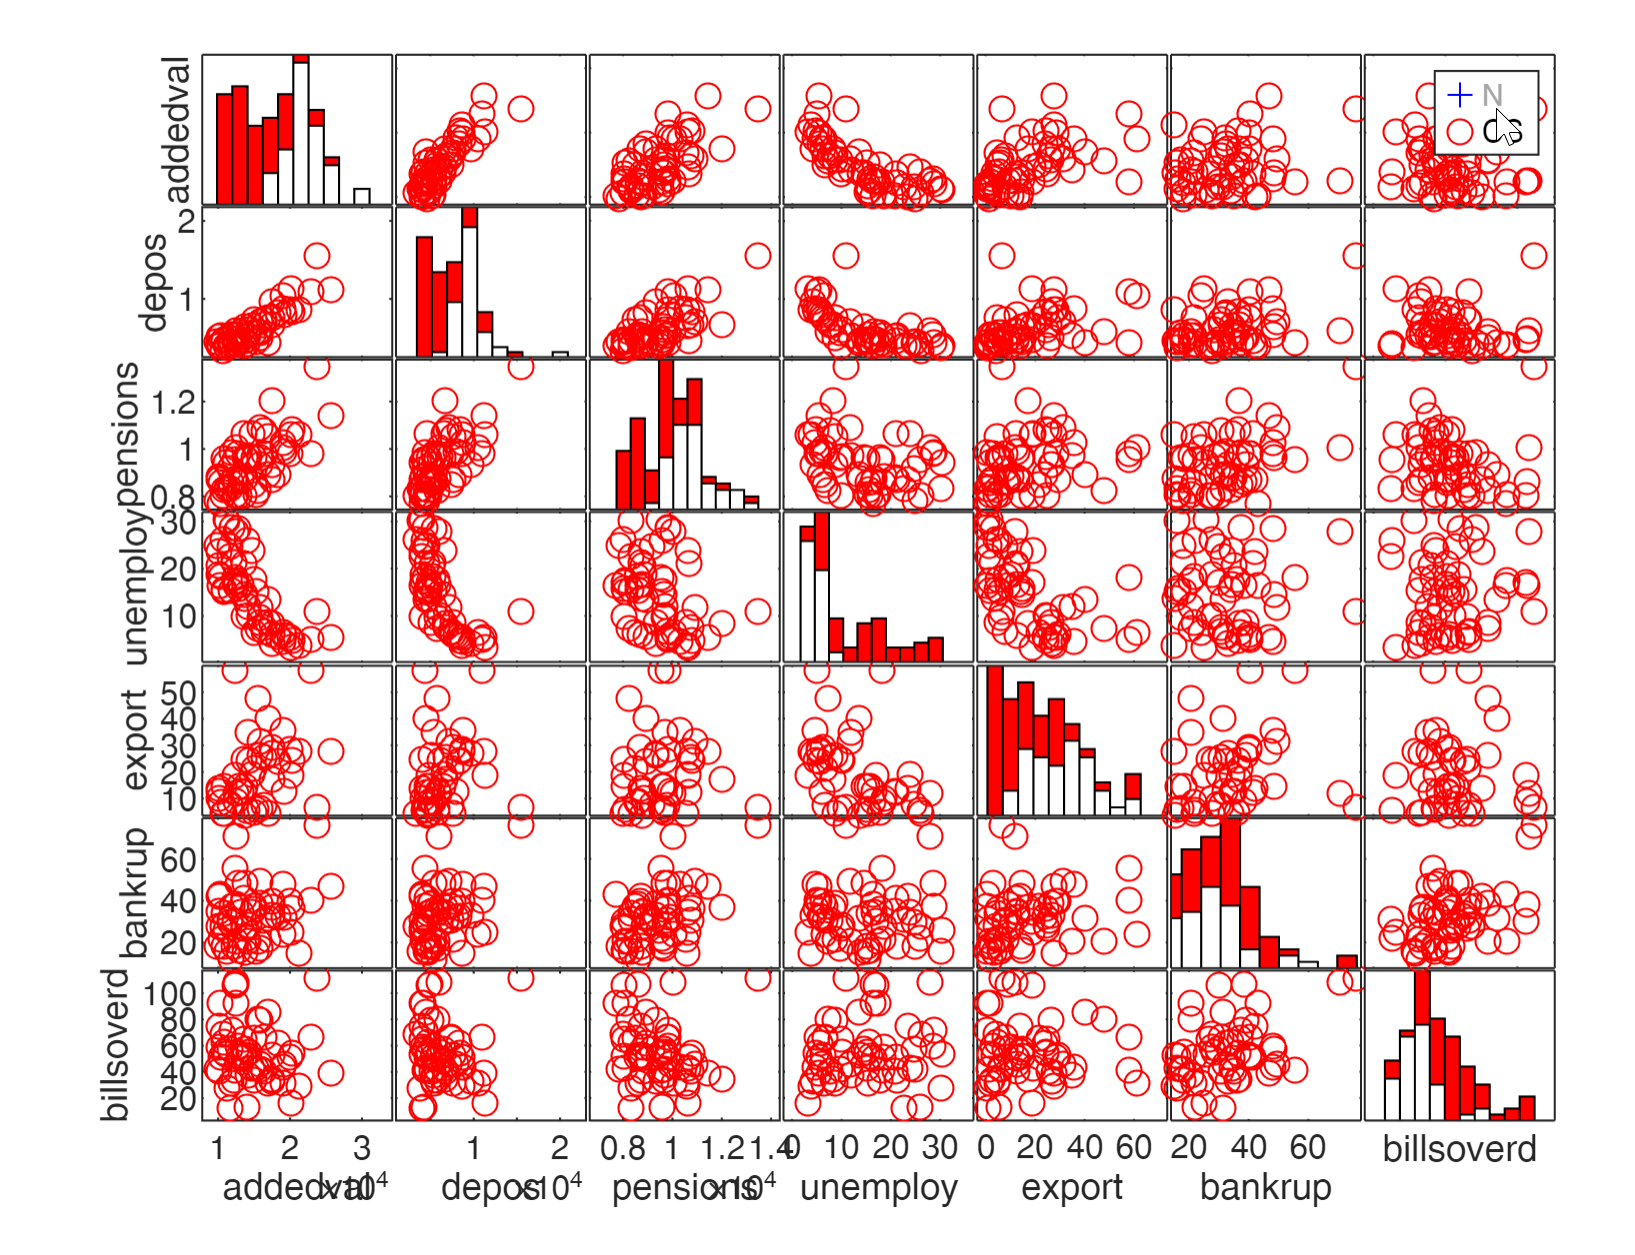

For the file which shows all the potentialities of spmplot see Personalized scatter plot matrices

List of all the FSDA functions which have been called in this example. Click on the hyperlink to see the full documentation